# The kernel trick

This question uses a subset of the iris data - only the sepal widths and sepal lengths for the versicolor and virginica classes:

clear all;
load('binary.mat', 'examples', 'labels');

This question is about training and visualising Support Vector Machines (SVMs) that use the kernel trick to produce nonlinear boundaries. You should use the whole dataset (without splitting) for training. Note that the dataset has already been z-score stadardised.

Marks are available for:

- An appropriate call to train an SVM on the whole dataset, using the kernel trick with a Radial Basis Function (RBF) kernel [3 marks]

- An appropriate call to train a *second* SVM on the whole dataset, using the kernel trick with an RBF kernel and a KernelScale of 0.1 [3 marks]

- Extending the `visualiseSVM()` function to give a helpful visualisation of any 2D model trained by the `fitcsvm()` function (the visualisation should at least include the decision boundary and the original training data) [8 marks]

- Using the `visualiseSVM()` function you have developed to produce a visualisation of each of the two SVMs you have trained [2 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

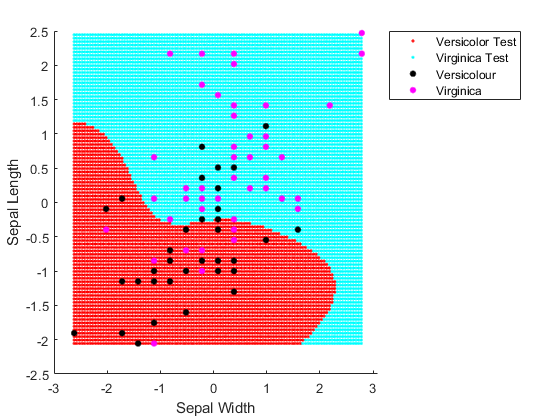

% add as many lines of code as you need below:

% train SVM on dataset with a Radial Basis Function kernel:
m = fitcsvm(examples, labels, 'KernelFunction', 'rbf');

% train a second SVM with a RBF of 0.1:
m2 = fitcsvm(examples, labels, 'KernelFunction', 'rbf', 'KernelScale', 0.1);

% visualise the trained SVMs with different Kernel Scales:
visualiseSVM(m, examples, labels)

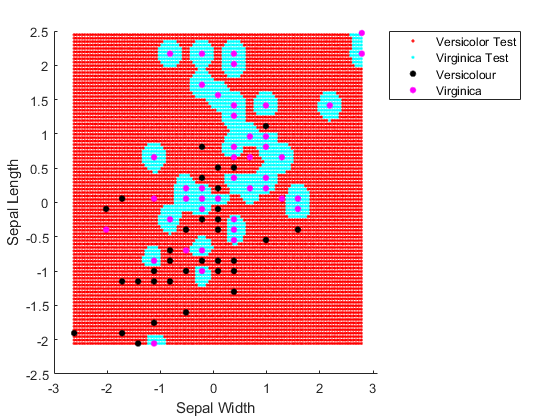

figure
visualiseSVM(m2, examples, labels)

function visualiseSVM(m, examples, labels)
    
    hold on
    
    % find the min and the max of both columns in example data
    min1 = min(examples{:,1});
    max1 = max(examples{:,1});
    min2 = min(examples{:,2});
    max2 = max(examples{:,2});
    
    
    % create an array to hold the grid of visualisation points
    generatedExamples = [];
    
    % create nested for loop to loop from the min and the max of each column
    for i=min1:0.05:max1
        for j=min2:0.05:max2
            % add each value in the grid to the array
            generatedExamples = [generatedExamples; [i j]];
        end
    end
    
    % predict the outcome of each set of values in the grid
    gridpredictions = predict(m, generatedExamples);
    % plot the points and their corresponding predictions
    gscatter(generatedExamples(:,1),generatedExamples(:,2),gridpredictions)
    
    % plot the original datapoints to visualize the classifiers accuracy:
    gscatter(examples{:,1},examples{:,2},labels,'km')
    xlabel("Sepal Width")
    ylabel("Sepal Length")
    legend('Versicolor Test', 'Virginica Test', 'Versicolour', 'Virginica', 'Location', "bestoutside");
 
    hold off
end